# **Projetar as funções de transferência dos filtros ativos que seguem com aproximação Butterworth:**

Deve ser apresentado  todo o equacionamento para se obter as funções de transferência a partir das funções normalizadas (polinômios de Butterworth). A partir da  função de transferência, apresentar a resposta em frequência do filtro  (magnitude e fase).  Apresentar ao menos simulações de sinais senoidais  (sobrepor sinal de entrada e saída) na banda passante, na frequência de  corte e na banda de rejeição dos filtros. Comparar os resultados obtidos na simulação com os previstos pela resposta em frequência.

K = 1;
s = tf("s");
interval = {0, 10^10};
rad_s = 2 * pi; % 1 Hz = 2 * pi rad/s

function simulate_filter_response(H, f, T)
    dt = 1e-5; 
    t = 0:dt:T; 
    u = sin(2 * pi*f*t); 
    
    [y, t_out] = lsim(H, u, t);
   
    figure;
    plot(t_out, u, 'b', t_out, y, 'r');
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    legend('Entrada', 'Saída');
    title(['Resposta do Filtro (f = ' num2str(f) ' Hz, T = ' num2str(T) ' s)']);
    grid on;
end

**1) Passa-baixas de primeira ordem com frequência de corte de 250 Hz.**

disp("Passa baixa 250Hz - 1ª Ordem");

Passa baixa 250Hz - 1ª Ordem


Hz = 250;
a = s / (Hz * rad_s);

butterworth_p_1 = a + 1;
H = 1 / butterworth_p_1


H =
 
    1571
  --------
  s + 1571
 
Continuous-time transfer function.
Model Properties


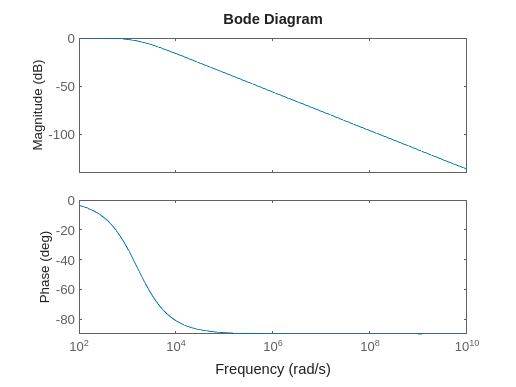


bode(H, interval)

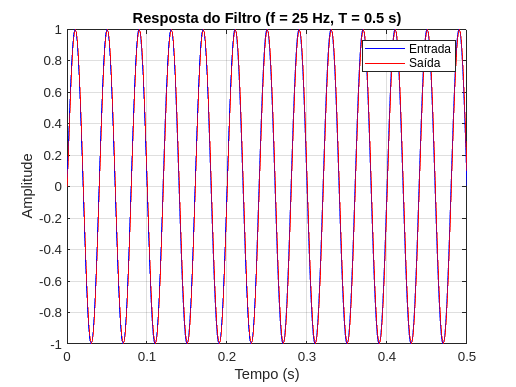


simulate_filter_response(H, Hz/10, 0.5);

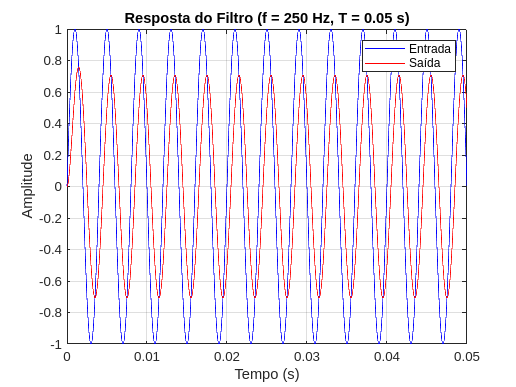

simulate_filter_response(H, Hz, 0.05);

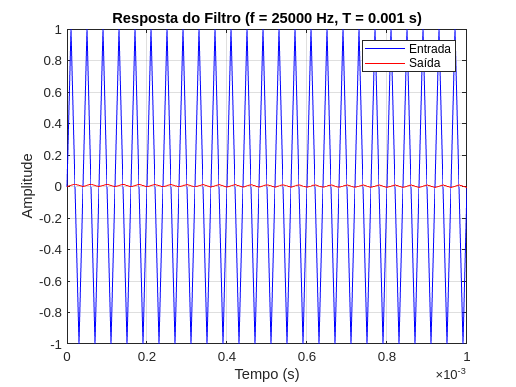

simulate_filter_response(H, Hz*100, 0.001);

**2) Passa-altas de primeira ordem com frequência de corte de 250 Hz. **

disp("Passa alta 250Hz - 1ª Ordem");

Passa alta 250Hz - 1ª Ordem


Hz = 250;
a = s / (Hz * rad_s);

butterworth_p_1 = a + 1;
H = (a^1) / butterworth_p_1


H =
 
       1571 s
  -----------------
  1571 s + 2.467e06
 
Continuous-time transfer function.
Model Properties


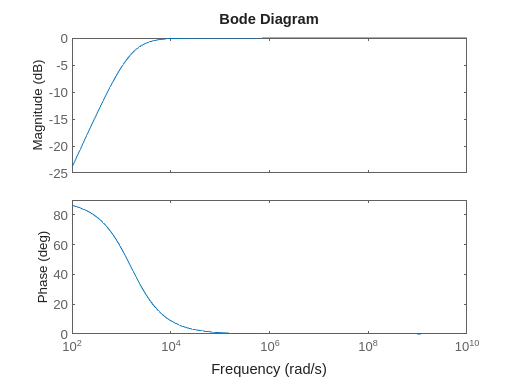


bode(H, interval)

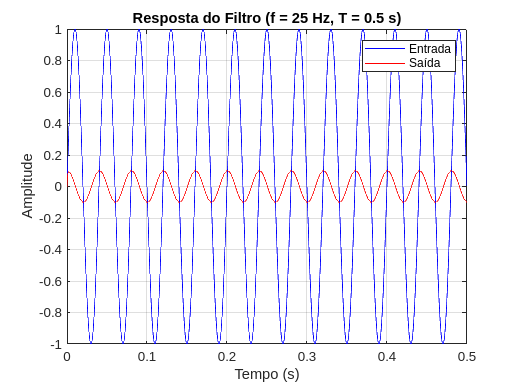


simulate_filter_response(H, Hz/10, 0.5);

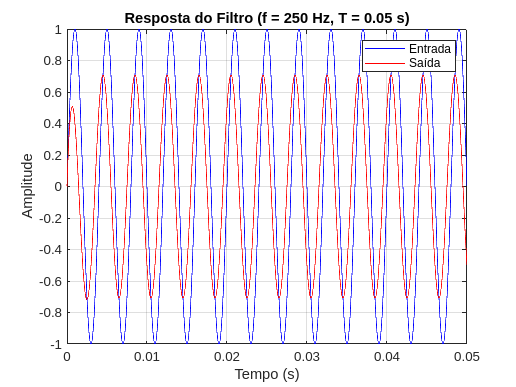

simulate_filter_response(H, Hz, 0.05);

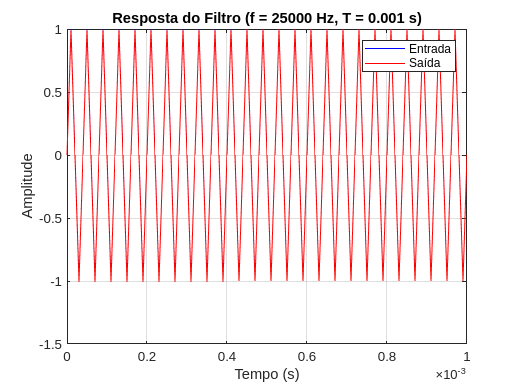

simulate_filter_response(H, Hz*100, 0.001);

**3) Passa-baixas de segunda ordem com frequência de corte de 250 Hz.**

disp("Passa baixa 250Hz - 2ª Ordem");

Passa baixa 250Hz - 2ª Ordem


a = s / (Hz * rad_s);

butterworth_p_2 = a^2 + a*1.4142 + 1;
H = 1 / butterworth_p_2


H =
 
              3.876e09
  --------------------------------
  1571 s^2 + 3.489e06 s + 3.876e09
 
Continuous-time transfer function.
Model Properties


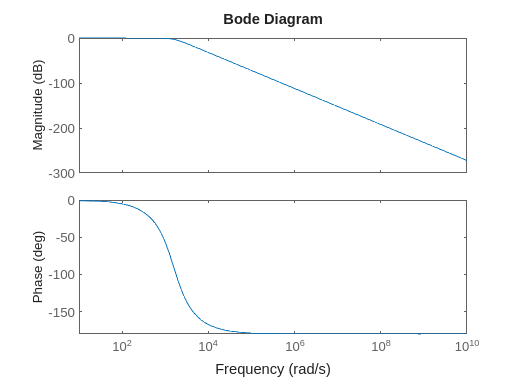


bode(H, interval)

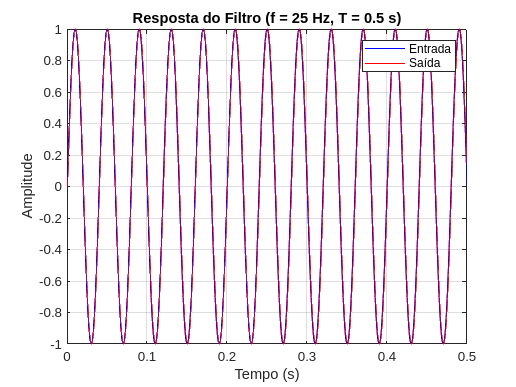


simulate_filter_response(H, Hz/10, 0.5);

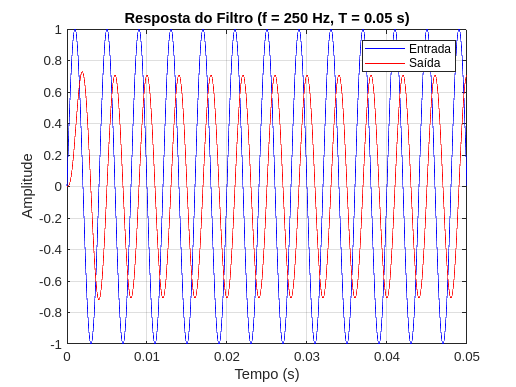

simulate_filter_response(H, Hz, 0.05);

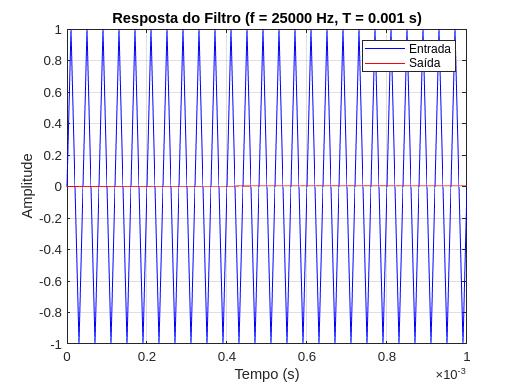

simulate_filter_response(H, Hz*100, 0.001);

**4) Passa-altas de segunda ordem com frequência de corte de 250 Hz. **

disp("Passa alta 250Hz - 2ª Ordem");

Passa alta 250Hz - 2ª Ordem


Hz = 250;
a = s / (Hz * rad_s);

butterworth_p_2 = a^2 + a*1.4142 + 1;
H = (a^2) / butterworth_p_2


H =
 
             3.876e09 s^2
  -----------------------------------
  3.876e09 s^2 + 8.61e12 s + 9.563e15
 
Continuous-time transfer function.
Model Properties


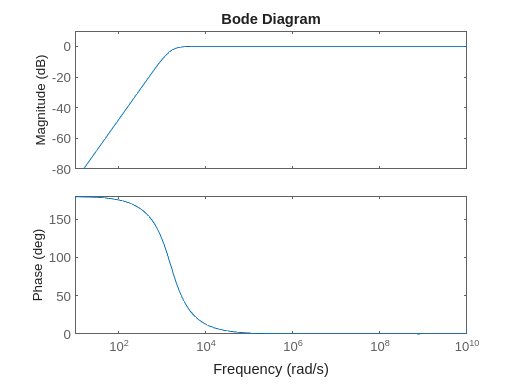


bode(H, interval)

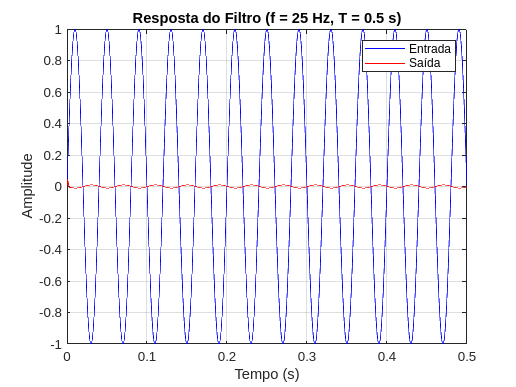


simulate_filter_response(H, Hz/10, 0.5);

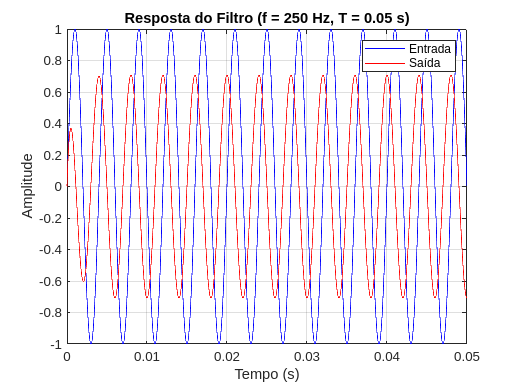

simulate_filter_response(H, Hz, 0.05);

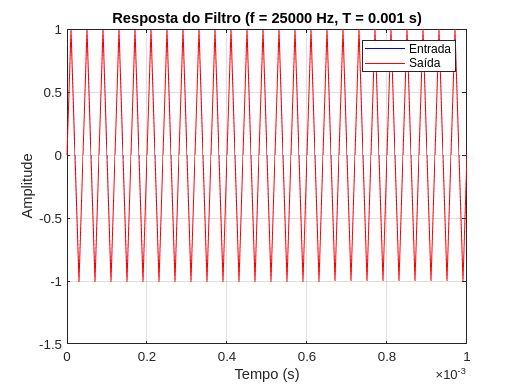

simulate_filter_response(H, Hz*100, 0.001);

**5) Passa-banda de segunda ordem com frequência central de 250 Hz e banda passante de 1000 Hz.**

disp("Passa Banda 250Hz ~ 1000Hz - 2ª Ordem");

Passa Banda 250Hz ~ 1000Hz - 2ª Ordem


% Passa baixa 1000
Hz1 = 1000;
a = s / (Hz1 * rad_s);
butterworth_p_2 = a^2 + a*1.4142 + 1;
H1 = 1 / butterworth_p_2;

% Passa alta 250
Hz2 = 250;
a = s / (Hz2 * rad_s);
butterworth_p_2 = a^2 + a*1.4142 + 1;
H2 = (a^2) / butterworth_p_2;

H = H1*H2


H =
 
                            9.614e20 s^2
  -----------------------------------------------------------------
  2.435e13 s^4 + 2.705e17 s^3 + 1.502e21 s^2 + 2.67e24 s + 2.372e27
 
Continuous-time transfer function.
Model Properties


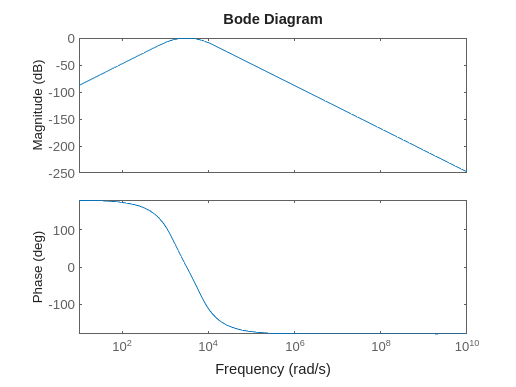

bode(H, interval)

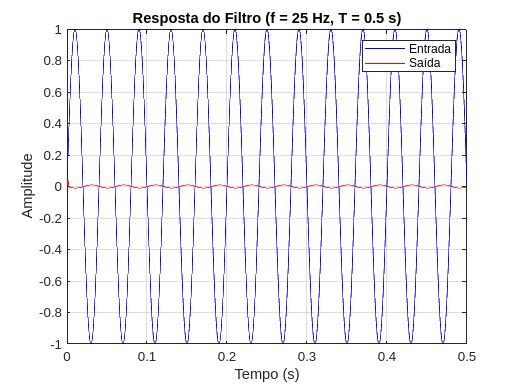


simulate_filter_response(H, Hz2/10, 0.5);

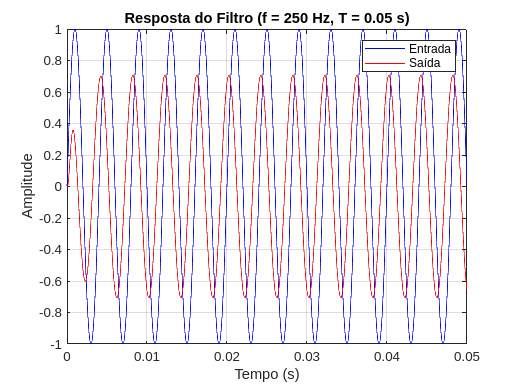

simulate_filter_response(H, Hz2, 0.05);

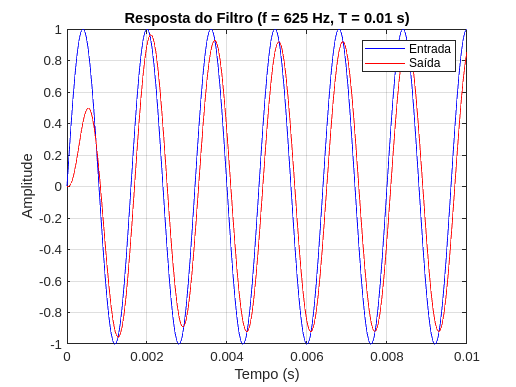

simulate_filter_response(H, ((Hz1 - Hz2)/2)+Hz2 , 0.01);

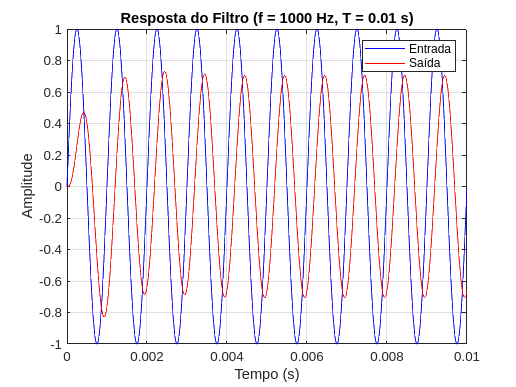

simulate_filter_response(H, Hz1, 0.01);

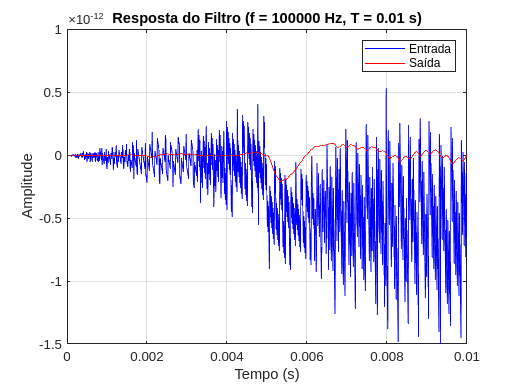

simulate_filter_response(H, Hz1 * 100, 0.01);

**6) Rejeita-banda de segunda ordem com frequência central de 250 Hz e banda passante de 1000 Hz.**